## Define teams

teams = {
    [2 2 4;
     4 1 2;
     4 1 1;
     3 1 1;
     4 1 2];
    [3 2 2;
     4 2 2;
     2 2 4;
     1 2 4];
    [4 2 3;
     3 2 2;
     2 5 3;
     2 2 4;
     3 2 2];
    [2 3 3;
     5 3 2;
     5 3 3;
     2 3 5;
     4 2 2];
    [2 2 4;
     4 2 2;
     4 3 4;
     2 2 4;
     2 3 3];
    [4 3 2;
     3 2 2;
     4 3 1;
     3 2 3;
     2 2 4];
    [4 3 2;
     2 5 5;
     2 4 4;
     4 2 3];
    [4 2 2;
     3 2 2;
     4 3 2;
     1 5 3;
     2 4 3];
    [5 2 1;
     2 2 3;
     5 2 1;
     2 3 3;
     1 2 5];
    [2 2 5;
     2 2 3;
     1 4 3;
     3 2 2;
     1 3 5];
    [2 3 3;
     5 2 1;
     2 4 5;
     1 4 3;
     2 3 4];
    [3 1 2;
     1 1 2;
     4 1 2;
     4 2 1;
     2 1 3];
    [1 4 3;
     1 3 2;
     2 2 4;
     5 2 2;
     3 2 2];
    [2 1 2;
     4 2 3;
     1 1 1;
     3 4 4;
     2 3 2];
    [3 1 2;
     2 2 4;
     3 1 2;
     2 1 1;
     1 1 2];
    [3 2 3;
     1 2 4;
     1 1 1;
     2 1 2];
    [2 2 3;
     1 1 1;
     2 4 5;
     1 2 3;
     5 1 2];
    [3 1 2;
     2 2 4;
     1 3 2;
     1 3 2;
     1 2 4];
    [1 4 3;
     2 2 2;
     4 1 2;
     2 1 2];
    [2 2 2;
     1 2 3;
     4 2 2;
     4 1 2;
     1 1 2]
};
numTeams = length(teams);
numSkills = size(teams{1}, 2);

## Skill overlap (max norm)

teamNormedOverlaps = [];
for i = 1:numTeams
    skills = teams{i};
    overlap = skills * skills';
    overlapNormed = overlap ./ max(max(overlap));
    totalOverlap = sum(sum(overlapNormed));
    teamNormedOverlaps(i) = totalOverlap;
end
teamNormedOverlaps'

ans =    17.7083
   12.8333
   14.7632
   17.3256
   15.3415
   18.7586
    9.9259
   17.0286
   17.1667
   16.4000


## Total team skills

teamSkillSums = zeros(numTeams, numSkills);
for i = 1:numTeams
    skills = teams{i};
    teamSkillSums(i, :) = sum(skills, 1);
end
teamSkillSums

teamSkillSums =     17     6    10
    10     8    12
    14    13    14
    18    14    15
    14    12    17
    16    12    12
    12    14    14
    14    16    12
    15    11    13
     9    13    18


teamSumSkillSums = sum(teamSkillSums, 2)

teamSumSkillSums =     33
    30
    41
    47
    43
    40
    40
    42
    39
    40


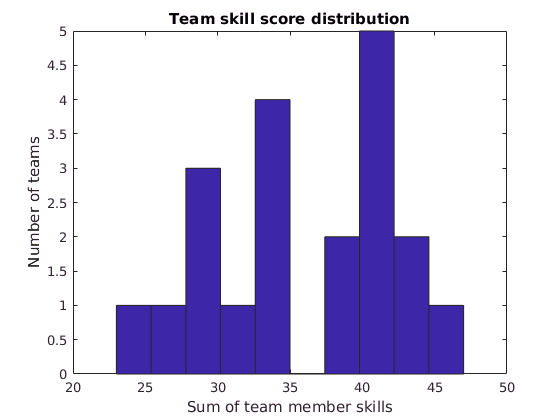


hist(teamSumSkillSums)
xlabel('Sum of team member skills');
ylabel('Number of teams');
title('Team skill score distribution')

Team skills normalized by team size

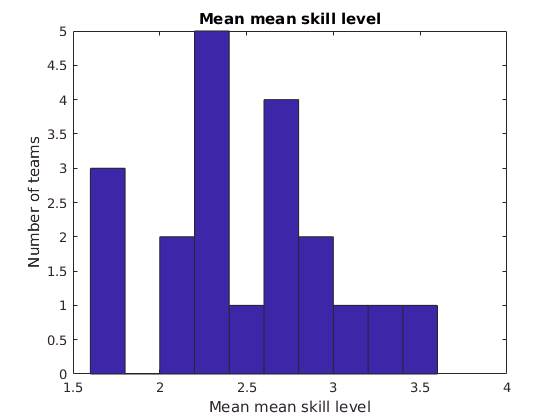

teamSkillSumsNormed = zeros(numTeams, 1);
for i = 1:numTeams
    teamSkillSumsNormed(i) = teamSkillSums(i) / size(teams{i}, 1);
end

hist(teamSkillSumsNormed)
xlabel('Mean mean skill level');
ylabel('Number of teams');
title('Mean mean skill level')